# Digital Potentiometer - MCP4562-103E/MS 10K

Purpose: The purpose of the digital potentiometer is to act as a variable resistor for Maximum Power Point Tracking (MPPT). MPPT allows for maximum power to be extracted from variable power sources such as solar panels. Within solar panels, the more current you draw, the less voltage you get, the less current you draw, the more voltage you get. 

In the context of solar panels, the conditions of the panels vary, thus power production varies as well. Utilizing MPPT, the point of maximum power production is able to be found through using the digital potnetiometer to vary the resistance, using Ohm's Law, allows for the current to be controlled.

Standard Modelling Techniques:

To model the MCP4562-103E/MS 10K, the behaviour must be captured in SimScape. By using its corresponding datasheet, it can be found the the behaviour of the digital potentiometer is determined by a resistor network. As the MCP4562-103E/MS 10K is 8 bits, it has 256 resistors, and 257 different resistance options. 

There are two terminals of note when modelling the digital potentiometer, P0W and P0B. P0B serves as a reference terminal, where its reference is the ground node. P0W is the wiper terminal, where it varies with reference to P0B. 

There are three main parameters that determine the output resistance $R_{WB}$, are $R_{AB}$, $R_{W}$, and $N$. $R_{AB}$ for the MCP4562-103/EMS 10K is fixed at $10k\Omega$.$R_{W}$is also a fixed value at $75\Omega$. Finally, N is the variable that determines what the output resistance is. The value of $N$ determines the location of the wiper terminal, where if N is 0, $R_{WB} = R_{W} = 75\Omega
$. However, if $N = 256$$R_{WB} = R_{AB} + R_{W} = 10000\Omega+ 75\Omega = 10075\Omega$. If $0 < N < 256$, $R_{WB}
$ can be calculated as: $R_{WB} = \frac{R_{AB}N}{256} + R_{W}$. Additionally, it is required that $N \geq 0$, otherwise the simulation will error.

This model can be captured through a simple MatLab script where $R_{WB}
$ is calaculated based on $N$, and is set as the resistance. A voltage supply is provided, as well as a $100\Omega$ resistor. Next, a current sensor is needed to output the current, as we will be able to capture the change in resistance using Ohm's Law. Finally, a sawtooth signal is injected into the model as a way to vary $N$, so that different reistances and currents can be viewed.

Datasheet:

https://ww1.microchip.com/downloads/aemDocuments/documents/OTH/ProductDocuments/DataSheets/22096b.pdf

## Model:

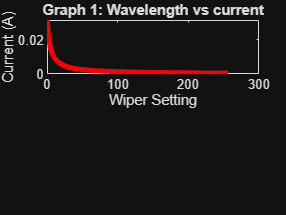

% Suppress all warnings
warning('off', 'all');

% Suppress specific algebraic loop warnings
warning('off', 'Simulink:Engine:AlgebraicLoop');

% Run the simulation and suppress command window output
evalc('sim_out = sim("C:\Users\timot\OneDrive\MATLAB\Components\Electrical\Models\Digital Potentiometer\digital_potentiometer_MCP4562_103EMS10K.slx")');

% Extract data for the first graph
wiper_setting = sim_out.graph1.Data(:, 1);
current = sim_out.graph1.Data(:, 2);

% Create a figure window
figure;

% First subplot
subplot(2, 1, 1);
plot(wiper_setting, current, 'r', 'LineWidth', 3); % Plot data
xlabel('Wiper Setting'); % Set x-axis label
ylabel('Current (A)'); % Set y-axis label
title('Graph 1: Wavelength vs current'); % Set title
set(gca, 'OuterPosition', [0, 0.5, 1, 0.5]); % Adjust outer position [left, bottom, width, height]